%Test of the Circular Statitics Idea

%This is for replacing the way we analyze FS reps of ODFS

%Raw SALS Intensity Data

%This is data coming from a section of bovine tendon
data_raw = [27 33 40 48 58 70 84 101 121 144 171 203 240 283 333 392 459 537 626 728 845 978 1129 1300 1494 1712 1957 2231 2538 2879 3258 3678 4142 4653 5213 5827 6496 7224 8014 8868 9788 10777 11836 12967 14170 15447 16796 18218 19710 21272 22900 24591 26341 28145 29998 31893 33822 35779 37755 39740 41726 43701 45655 47578 49458 51283 53044 54727 56324 57822 59211 60483 61628 62637 63505 64223 64788 65194 65439 65520 65439 65194 64788 64223 63505 62637 61628 60483 59211 57822 56324 54727 53044 51283 49458 47578 45655 43701 41726 39740 37755 35779 33822 31893 29998 28145 26341 24591 22900 21272 19710 18218 16796 15447 14170 12967 11836 10777 9788 8868 8014 7224 6496 5827 5213 4653 4142 3678 3258 2879 2538 2231 1957 1712 1494 1300 1129 978 845 728 626 537 459 392 334 283 240 203 171 144 121 101 84 70 58 48 40 33 27 22 18 15 12 10 8 7 6 5 4 3 4 5 6 7 8 10 12 15 18 22 27 33 40 48 58 70 84 101 121 144 171 203 240 283 334 392 459 537 626 728 845 978 1129 1300 1494 1712 1957 2231 2538 2879 3258 3678 4142 4653 5213 5827 6496 7224 8014 8868 9788 10777 11836 12967 14170 15447 16796 18218 19710 21272 22900 24591 26341 28145 29998 31893 33822 35779 37755 39740 41726 43701 45655 47578 49458 51283 53044 54727 56324 57822 59211 60483 61628 62637 63505 64223 64788 65194 65439 65520 65439 65194 64788 64223 63505 62637 61628 60483 59211 57822 56324 54727 53044 51283 49458 47578 45655 43701 41726 39740 37755 35779 33822 31893 29998 28145 26341 24591 22900 21272 19710 18218 16796 15447 14170 12967 11836 10777 9788 8868 8014 7224 6496 5827 5213 4653 4142 3678 3258 2879 2538 2231 1957 1712 1494 1300 1129 978 845 728 626 537 459 392 334 283 240 203 171 144 121 101 84 70 58 48 40 33 27 22 18 15 12 10 8 7 6 5 4 3 4 5 6 7 8 10 12 15 18 22];

%New Data point
examplePoint = data_point;
examplePoint.intensity_data = data_raw;

%Normalize data and generate fourier
examplePoint.Normalize;
examplePoint.GenerateFourier(14);
examplePoint.ComputeStats;

examplePoint.mean_odd

ans = 2.9671

examplePoint.mean_odf

ans = 2.9654

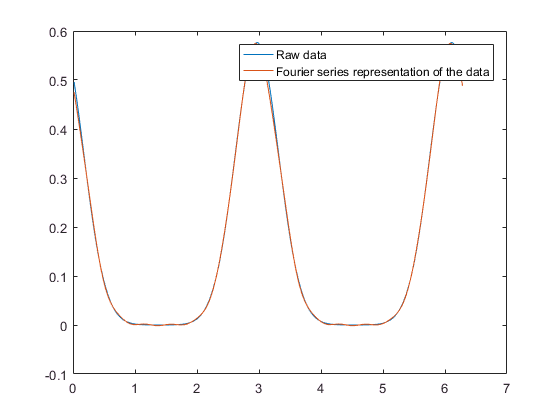


%plot ODD and ODF
figure;
plot(examplePoint.theta, examplePoint.odd);
hold on;
plot(examplePoint.theta, examplePoint.odf);
hold off;
legend('Raw data', 'Fourier series representation of the data');


%Dive into the world of circular statistics
vals = examplePoint.odf.*(exp(1i.*examplePoint.theta));
m1 = simpsons(vals, examplePoint.theta(1), examplePoint.theta(end), 359);

PrefD = angle(m1)

PrefD = 3.1323

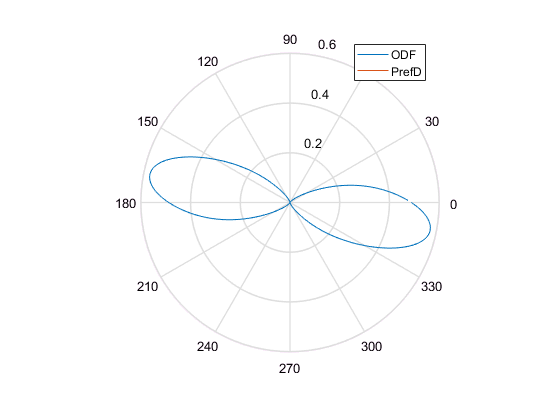


figure;
polar(examplePoint.theta, examplePoint.odf);
hold on;
plot(angle(m1), abs(m1));
hold off;
legend('ODF', 'PrefD');